# spatial bandwidth 2P line analysis

addpath('221_3 tecta flfl Left','233_3 flfl','399_1 flfl Left','399_2 tecta flfl Left','399_2 tecta flfl Right','406_1 tecta flfl right','406_2 flfl left','406_2 flfl right','399_1 flfl Right','406_1 tecta flfl left')


% load control
con1 = load('spatialAnalysisLine233_3L.mat');
con2 = load('spatialAnalysisLine399_1L.mat');
con3 = load('spatialAnalysisLine406_2L.mat');
con4 = load('spatialAnalysisLine406_2R.mat');
con5 = load('spatialAnalysisLine399_1R.mat');
% load cKO
cko1 = load('spatialAnalysisLine221_3L.mat');
cko2 = load('spatialAnalysisLine399_2L.mat');
cko3 = load('spatialAnalysisLine399_2R.mat');
cko4 = load('spatialAnalysisLine406_1R.mat');
cko5 = load('spatialAnalysisLine406_1L.mat');

perctile = 0.75;
scale = 425/256;
con1BW = get2PSpatialBW(con1,perctile)

con1BW =    103    84    50    25    15    18    34    20    31    19    49    70    50    42    45    47    13    21    40    22    53    48    39    31    64    50    48    26    18    25    37    28    25    33    37    21    50    46    18    31    23    25    35    49    23    43    75    66    41    56


con2BW = get2PSpatialBW(con2,perctile)

con2BW =     39    27    22    37    25    38    26    60    65    36    27    28    29    29    70    74    19    35    46    17    28    28    28    21    54    46    20    39    32    23    25    22    29    57    72    32    40    27    27    35    23    29    26    19    38    28    65    23    47    22


con3BW = get2PSpatialBW(con3,perctile)

con3BW =     24    24    45    45    27    55    23    15    29    37    29    22    22    21    53    62    59    21    39    44    46    45    29    25    51    15    33    68    63    64    45    61    27    60    38    28    28    36    36


con4BW = get2PSpatialBW(con4,perctile)

con4BW =     40    20    29    29    27    31    45    22    35    22    18    42    61    21    15    47    30    30    24    43    49    15    28    28    29    61    65    44    52    26    59    29    31    53    49    17    44    21


con5BW = get2PSpatialBW(con5,perctile)

con5BW =     32    17    21    25    24    51    19    38    20    37    41    37    79    34    42    47    40    41    23    46    41    50    52    25    18    38    36    51    57    59    15    30    15    32    18    37    32    31    40    49    30    45    53    62    66    14    46    19    23    35



cko1BW = get2PSpatialBW(cko1,perctile)

cko1BW =     37    39    29    31    43    40    34    37    31    30    25    61    53    53    54    33    11    59    29    32    21    29    55    54    29    31    21    30    17    32    26    27    54    24    30    29    57    31    35


cko2BW = get2PSpatialBW(cko2,perctile)

cko2BW =     60    18    17    71    73    22    21    17    32    26    45    61    37    37    24    35    18    36    50    43    22    28    15    24    19    39    24    24    23    39    39    33    33    54    30    27    30    37    15    29    19    22    24    28    36    20    33    54    68    64


cko3BW = get2PSpatialBW(cko3,perctile)

cko3BW =     41    15    16    16    38    22    15    50    29    20    34    32    19    12    25    46    15    14    25    10    35    24    14    28    15    17    69    42    42    22    18    18    16    16    21    28    90    88    21    23    38    26    22    27    30    16    55    25    16    18


cko4BW = get2PSpatialBW(cko4,perctile)

cko4BW =     72    31    28    39    34    26    22    33    22    24    42    72    58    43    21    33    46    27    31    20    28    18    37    33    46    40    27    48    36    29    23    31    39    21    36    30    42    49    28    41    25    43    30    49    49    27    74    73    57    37


cko5BW = get2PSpatialBW(cko5,perctile)

cko5BW =     21    20    23    26    50    30    39    27    23    17    27    49    25    31    31    14    26    38    18    21    30    68    24    39    47    18    35    38    35    28    22    13    17    15    21    39    73    23    26    23    25    47    29    18    38    14    35    26    41    42



conBW = [con1BW,con2BW,con3BW,con4BW,con5BW]*scale;
ckoBW = [cko1BW,cko2BW,cko3BW,cko4BW,cko5BW]*scale;

length(conBW)

ans = 236

length(ckoBW)

ans = 253

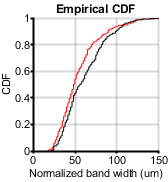


figure
h1 = cdfplot(ckoBW);
hold on
h2 = cdfplot(conBW);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized band width (um)');
ylabel('CDF');
xlim([0 150])
xticks([0 50 100 150])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(ckoBW,conBW);
 p

p = 0.0059

 
 cxBWmean = [mean(con1BW),mean(con2BW),mean(con3BW),mean(con4BW),mean(con5BW)]*scale;
 tectacxBWmean = [mean(cko1BW),mean(cko2BW),mean(cko3BW),mean(cko4BW),mean(cko5BW)]*scale;
 
 conditions2 = {'Control','Cx26 cKO'};
dim = [1 1.8];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(cxBWmean,tectacxBWmean,conditions2,ylbl1,dim);

     0



ylim([0 80])
yticks([0 20 40 60 80])
p1

p1 = 0.0958

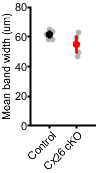


subP = handleTheSubplot({fig1,fig1,fig1},[1 3]);

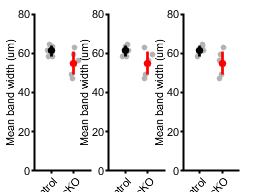

figQuality(subP,gca,[2.75 2])


[h p] = ttest2(cxBWmean,tectacxBWmean,'Vartype','unequal')

h = 0

p = 0.1122

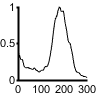

% plot spatial profiles

 figure
  plot(con1.smdfof(:,432)./max(con1.smdfof(:,432)),'k')
  ylim([0 1])
 figQuality(gcf,gca,[1 1])

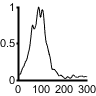


figure
  plot(con1.smdfof(:,750)./max(con1.smdfof(:,750)),'k')
  ylim([0 1])
 figQuality(gcf,gca,[1 1])

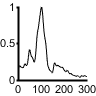

 
 
 figure
  plot(cko2.smdfof(:,1899)./max(cko2.smdfof(:,1899)),'k')
  ylim([0 1])
 figQuality(gcf,gca,[1 1])

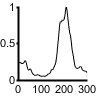


figure
  plot(cko2.smdfof(:,1222)./max(cko2.smdfof(:,1222)),'k')
  ylim([0 1])
 figQuality(gcf,gca,[1 1])